# T2-1. Getting the PSD from data through sample spectrum

## Introduction

In this tutorial you will learn how to estimate the PSD of a random process from a time series through the sample spectrum estimator. The time series is assumed to be a realisation of a zero-mean random process. The PSD estimation is obtained from the squared magnitude of the discrete-time Fourier transform (DTFT) of the data. 

The dataset employed in this tutorial is '*datasets/dataset_03_Mann_1V*', which includes a synthetic time series of the longitudinal component of turbulent wind fluctuation (zero mean), according to the Mann's model, and the related true spectrum. This allows comparison between the estimated PSD and the true PSD. 

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters
N_f             = 100;      % number of elements of the frequency vector


%%% Plot parameters
font_size       = 18;
figure_position = [0 0 1000 400];
CC              = colororder;
color_estimated = CC(5,:);
color_true      = CC(4,:);

Load the dataset. It consists of two objects, one in the form of a `data` object, and one in the form of a `S` object. For details related to the fields of these objects, see functions `initialise_data` and `initialise_S`.

load dataset_03_Mann_1V.mat

Have a look at the time series considered. 

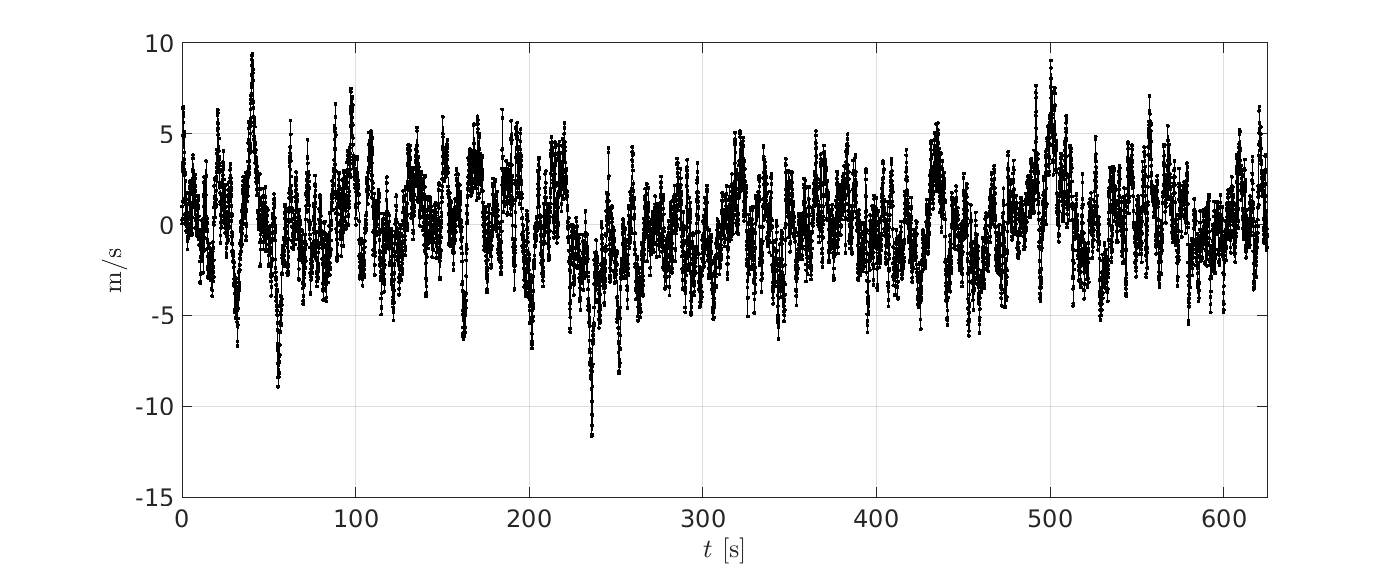

figure

x = data_Mann.x_values;
y = data_Mann.y_values;
plot(x,y,'.-k')

grid on
xlabel('$t$ [s]','Interpreter','latex')
ylabel('m/s','Interpreter','latex')
xlim([0 data_Mann.x_values(end)])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

Note the sampling time and the time span of the data. They are useful to define the maximum frequency, $f_{max}$, and the minimum frequency, $f_{min}$. The frequency vector to evaluate the sample spectrum will be defined within this frequency range.

delta_t     = data_Mann.x_parameters.delta_x;   % seconds
t_sim       = delta_t*data_Mann.x_parameters.N; % seconds

f_max       = 1/(2*delta_t);
f_min       = 1/t_sim;

f_vector    = linspace(f_min,f_max,N_f);

Initialise an S object  with the fields required by function get_S_data`_sample_spectrum`. 

S0 = initialise_S('x_values', f_vector);

Compute the sample spectrum of the data. Since the data is univariate, there is no need to specify the column with parameter `k_index` (see details in function get_S_data`_sample_spectrum`).

S_sample = get_S_data_sample_spectrum(data_Mann, S0);

Plot the obtained sample spectrum together with the true spectrum.

figure

x = S_sample.x_values;
y = S_sample.y_values;
plot(x,y,'.-','color',color_estimated)

hold on

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,y,'.-','color',color_true)

legend({'$S_{sample}$','$S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','best')
grid on
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$ \, s$^{-1}$','Interpreter','latex')

set(gca,'fontsize',font_size)

Sometimes the spectrum is better represented in x-log scale.

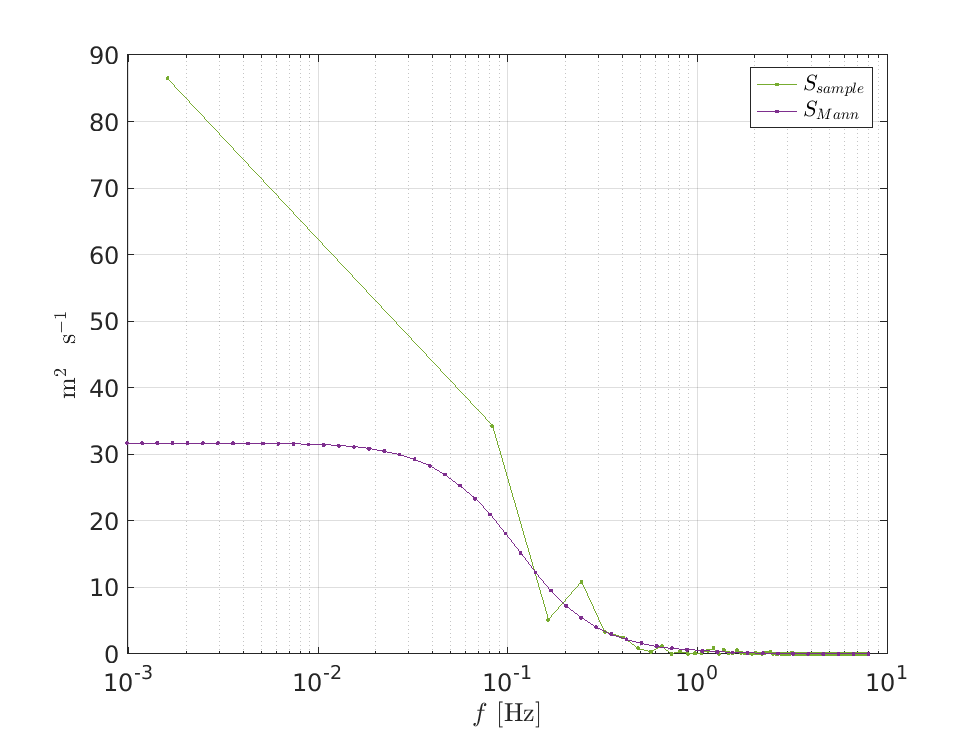

set(gca,'Xscale','log')

The problem of using a linearly spaced `f_vector` together with the x-log scale is that the sprectrum shows irregular resolution. This can be addressed by defining a logarithmically spaced vector `f_vector`.

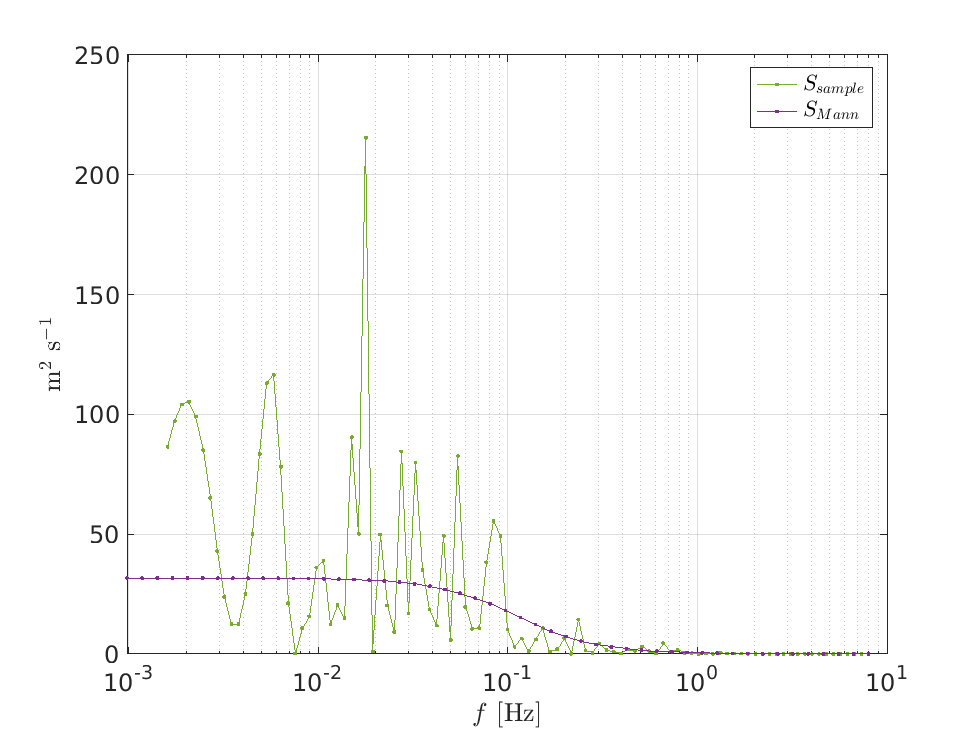

f_vector_log        = logspace(log10(f_min),log10(f_max),N_f);
S0_log              = initialise_S('x_values', f_vector_log);
[ S_sample_log ]    = get_S_data_sample_spectrum(data_Mann, S0_log);

figure

x = S_sample_log.x_values;
y = S_sample_log.y_values;
plot(x,y,'.-','color',color_estimated)

hold on

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,y,'.-','color',color_true)

grid on
legend({'$S_{sample}$','$S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$ s$^{-1}$','Interpreter','latex')

set(gca,'Xscale','log')
set(gca,'fontsize',font_size)

For the case of wind turbulence, two common representations are the product $f \cdot S$ in log-linear scales, and $S$ in log-log scales.

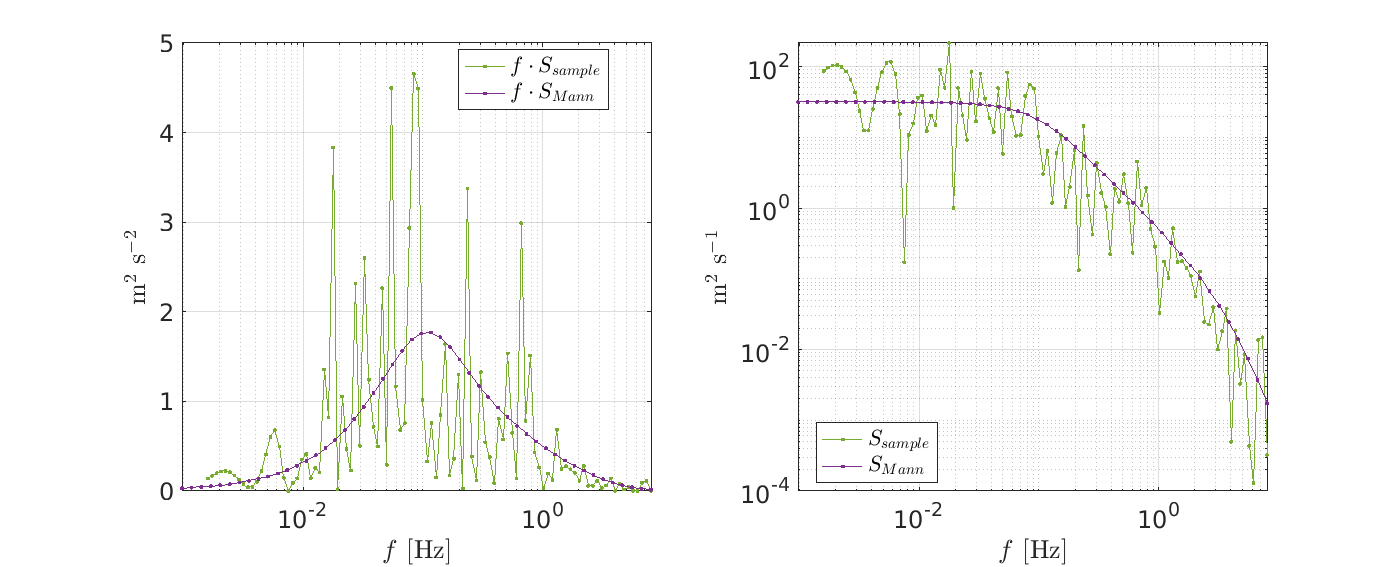

figure


subplot(1,2,1)

x = S_sample_log.x_values;
y = S_sample_log.y_values;
plot(x,x.*y,'.-','color',color_estimated)

hold on

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,x.*y,'.-','color',color_true)

grid on
legend({'$f \cdot S_{sample}$','$f \cdot S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$  s$^{-2}$','Interpreter','latex')
set(gca,'Xscale','log')
set(gca,'fontsize',font_size)


subplot(1,2,2)

x = S_sample_log.x_values;
y = S_sample_log.y_values;
plot(x,y,'.-','color',color_estimated)

hold on

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,y,'.-','color',color_true)

grid on
legend({'$S_{sample}$','$S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$ s$^{-1}$','Interpreter','latex')

set(gca,'Xscale','log')
set(gca,'Yscale','log')
set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

## Remarks

- Note that the PSD is a continuous function of the frequency, and it can be evaluated at any frequency value. 

- However, the PSD estimated from a discrete time series is periodic for frequencies higher thant $f_{max} $. You can check it just by changing `f_vector` accordingly. 

- Also, the estimated spectrum for frequencies below $f_{min}$ is likely to be inaccurate because the time simulation of the data, `t_sim`, is not long enough to capture such small frequencies.

- As it can be seen, the sample spectrum is not a good PSD estimator. Actually, it is an inconsistent estimator because the variance of the estimation does not decrease with $N \rightarrow \infty$, $N$ being the length of the time series. More accurate estimators are the Blackman-Tukey, Daniell, and Welck estimators, see corresponding functions in folder '`S/S_data``'.`

- Since the sample spectrum is based on the DTFT and the DTFT is a smooth function of the frequency, the spectrum is also a smooth function. The seemingly spiking behaviour in a plot can be reduced just by increasing the number of points in the frequency vector (`N_f`).